Anonymous function

Inmatlab, "function" is one of features. Two methods to define  a function are

1) declare " function" with its name , in , out and save in your working directory

2) use an anonymous function if it is a little n=bit simple.

For example

clear all
% samling 
x =[1 2 3];
f = x.^2
%define a function 
g = @(x) x.^2
g(1)
g(x)

- Introduction to "Chebfun" 

- Chebfun is an open-source package for computing with functions. In 2019 matlab it is provided as a toolbox in amtlab( I do not know in case of the late version, hwowever in 2016 not 

- It is a numerical analysis executable on matlab environment

- numerical not but sampling (or symbolic math) but by function, chebchev funtions 

    [https://www.chebfun.org/](https://www.chebfun.org/)

 -It is numerical approximation by chebchev functions not by sampling

-There are wonderful features over conventioanl matlab, especially  ODE or calculus.

-  plot a function

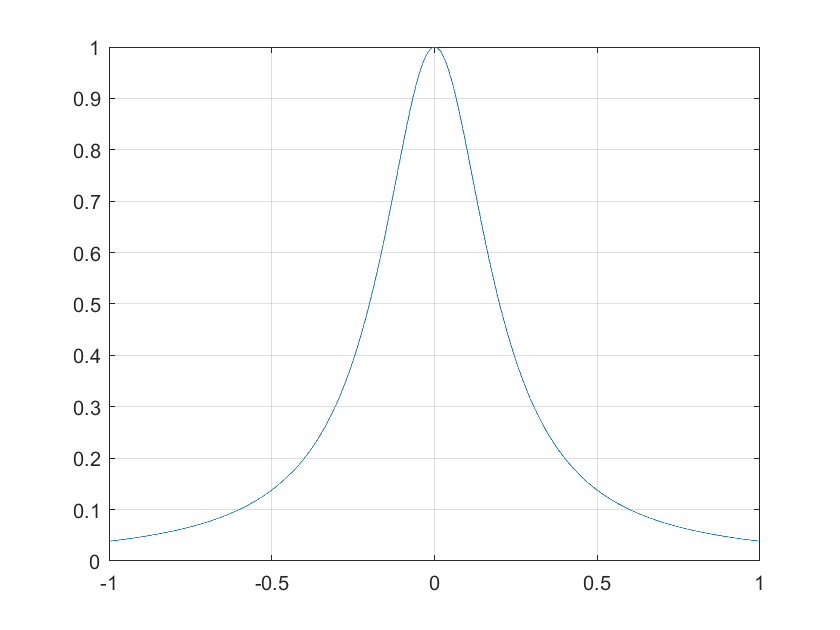

clear all
f = chebfun(@(x) 1./(1+ 25*x.^2));
plot(f); grid on

Here "f" is declared by "chebfun" using an anonymous function method.

What is the difference between 

      @(x)  f(x)

      chebfun(@(x)   f(x)  )

In case of anonymous function, to get the value, there should be sample points.  In case of "chebfun", sample points are already defined. How? using chechev functions. It is peculiar and special features on chebfun.Hence "chebfun" is a numerical method but without sampling points. How about accuracy? it is enough to be accurate so that you may not be worried about the number of samples in the (anonymous) function methods. 

 I like "chebfun" when I draw a piecewise function.

% piecewise function
g = chebfun({@(x) x.^2 , 1, @(x) 4-x}, [-1 1 2 4]);
plot(g); 


- Operators; differentiator (Ch.2.4)

Consider 

                           
$$\frac{\textrm{df}}{\textrm{dx}}=\frac{d}{\textrm{dx}}\left(\cos \left(\pi x\right)\right)\;,\;\;\;\;\;x\in \left\lbrack 0\;20\right\rbrack$$
 

Here in "chebfun" cmd is

clear all;
f = chebfun(@(x) cos(pi*x), [0 20])

f =

   chebfun column (1 smooth piece)
       interval       length     endpoint values  
[       0,      20]       65         1        1 
vertical scale =   1 



df = diff(f);
plot(f); hold on
ddf = diff(f,2);
plot(df, 'r')
ddf = diff(f,3)

ddf =

   chebfun column (1 smooth piece)
       interval       length     endpoint values  
[       0,      20]       62  -4.1e-09  2.9e-09 
vertical scale =  31 



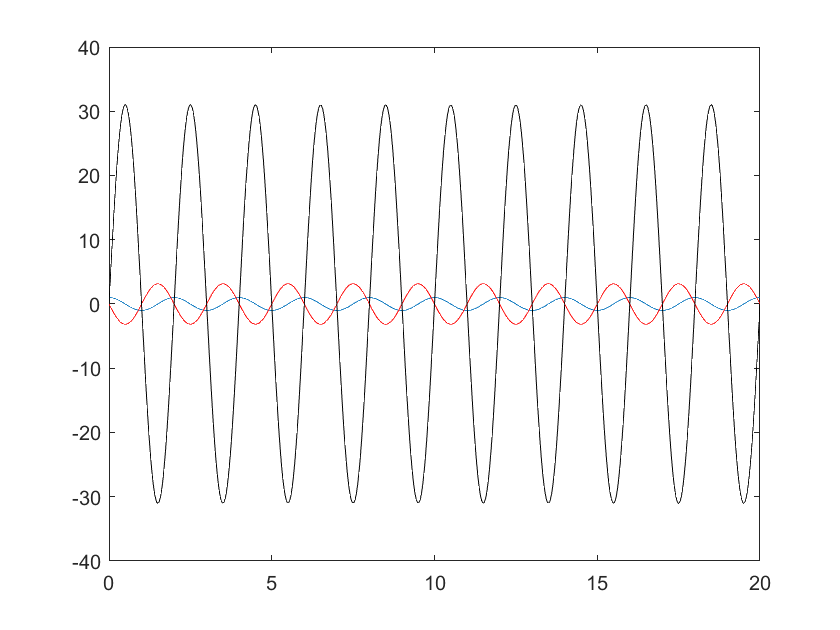

plot(ddf,'k'); hold off

Hence the derivatives of a function can be derived at any finite order. Rememver

this is NOT a analytic solution as in "symbolic math" but a numerical solution.

- operators - definite integral

Consider 

             
$$f=\int_0^1 t^2 \textrm{dt}$$


 1) symbolic method - analytic 

clear all
syms t
f = t^2;
int(f)
int(f,[0 1])

At leaset If there is an analytic solution, it gives a solution.

2) function method - numerical 

Another method  numerically.  

clear all;
f = @(t) t.^2;
integral(f,0,1)

3) "chebfun" method

clear all;
f=chebfun(@(t) t.^2, [0 1]);
integral(f,0,1)
sum(f)

The results of all three are the same. But numerically what about "chebfun"?

consider  a data 

                      
$$\textrm{data}\;=\left\lbrack 1\;\;2\;\;3\;\;4\;\;5\right\rbrack$$


to calculate all the data

                     
$$\textrm{sum}\;=\sum_{i=1}^5 \textrm{data}\left(i\right)$$
 

and calculate a cumulative sum as 

                  
$$\textrm{cumsum}\left(k\right)=\sum_{i=1}^k \textrm{data}\left(i\right)\;$$


in matlab cmd. In the 3) example there is "sum" cmd. This cmd is 

clear all;
data = [ 1 2 3 4 5];
sum(data)
cumsum(data)

You may use not  "sum" or "cumsum" for (anonymous) function without sample points. However chebfun is able to do. One of my favorite cmd is indefinite integral. 

Consider an indefinite integral 

              
$$\;f=\int_0^x \frac{1}{\sqrt{2\pi \;}}\exp \left(-\frac{t^2 }{2}\right)\textrm{dt}$$


You may use "chebfun" as a new command, with a indefinite integral,

clear all
f = chebfun(@(t) (1/sqrt(2*pi))*exp((-t.^2)/2), [-10 10]);
I = sum(f)
h = cumsum(f);
plot(f,'b'); hold on; grid on
plot(h,'k')

-  Operator in chebfun (ch.7.3)

1) First - order  ODE

Consider  

                  
$$\frac{\textrm{dx}}{\textrm{dt}}=-x\;,x\left(0\right)=1$$


To get the solution in chebfun 'chebop' is introduced.

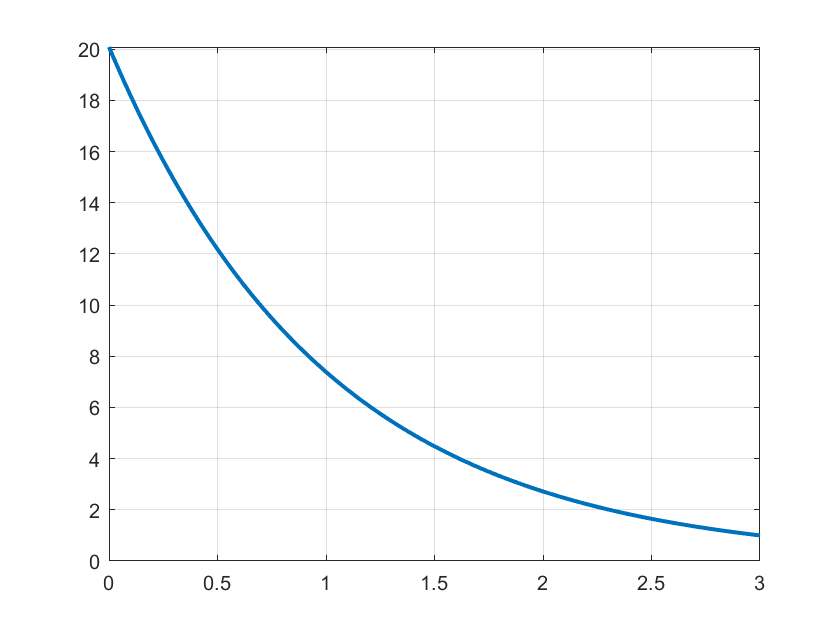

clear all;
LW = 'Linewidth';
L = chebop(0,3);
L.op = @(t,x) diff(x,1) +x;
L.rbc = 1;
x =L\0;
plot(x, LW,2); grid on

Here an operator is declared as "chebop" with a domain [initial, final]. 

The operator   L.op = @(t,x) f(x)  is (t,x) : t is a variable x is a function of t

The boundary condition is   L.lbc: means x(initial) = x(0), here .lbc: left boundary condition.

 And the solution is calculated as 

      x = L \ (input)

Done. It is simple. Fro example, with different initial points 

              
$$\frac{\textrm{dx}}{\textrm{dt}}=x-x^3 \;,x\left(0\right)=\left\lbrack -0\ldotp 5\;\;-0\ldotp 1\;\;0\ldotp 1\;\;0\ldotp 5\right\rbrack$$


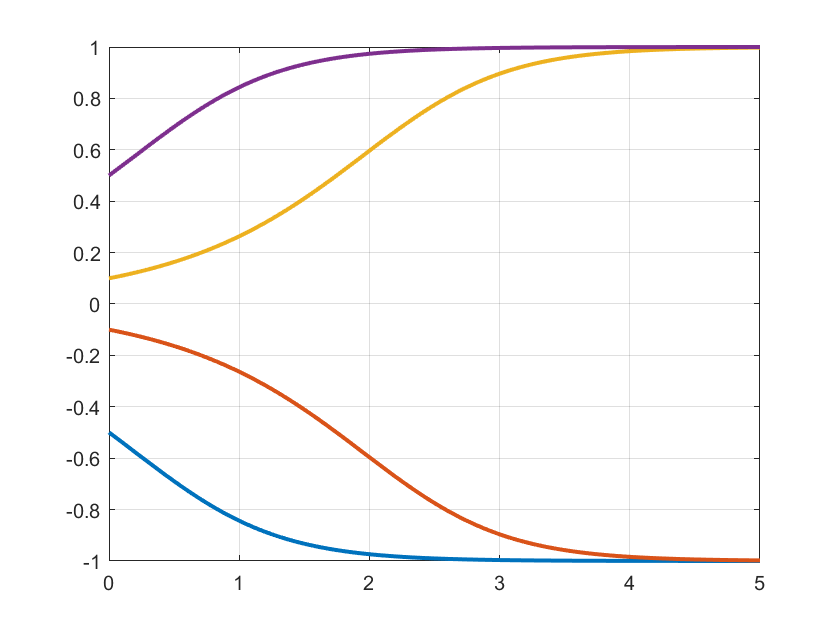

clear all;
LW = 'linewidth';
L = chebop(0,5);
L.op = @(t,x) diff(x,1) - x + x.^3;
Init = [-0.5 -0.1 0.1 0.5];
for i = 1:4
    L.lbc = Init(i);
    x =L\0;
    plot(x,LW,2); grid on;
    hold on
end 
hold off

-  Solving Second order differential : (chebfun guide chap.7)

Consider

                   
$$\frac{d^2 x}{{\textrm{dt}}^2 }+t^{3\;} x=1,t\in \left\lbrack 0,3\;\right\rbrack ,x\left(0\right)=0,\frac{\textrm{dx}}{\textrm{dt}\;}\left(0\right)=0$$


clear all
L = chebop(0, 3);
L.op = @(t,x) diff(x,2) + t.^3.*x;
L.lbc= [0;0];
x = L\1;
plot(x)

We may check  at the boundary values

x(0)
dx = diff(x)
dx(0)

In the second order DE, there should be two boundary conditions.Here the boundary conditions are the initial conditions

   
$$x\left(0\right)=0,\frac{\textrm{dx}}{\textrm{dt}\;}\left(0\right)=0$$


Or 

   
$$x\left(0\right)=0,\;x\left(3\right)=5$$


then the solution is

clear all
L = chebop(0, 3);
L.op = @(t,x) diff(x,2) + t.^3.*x;
L.lbc = 0;
L.rbc = 5;
x = L\1;
plot(x)
% check the final condition
x(3)

   Or the initial and final condition are

       
$$x\left(0\right)=0,\frac{\textrm{dx}}{\textrm{dt}\;}\left(3\right)=-1$$


clear all
L = chebop(0, 3);
L.op = @(t,x) diff(x,2) + t.^3.*x;
L.lbc = 0;
L.rbc = @(x) diff(x) +1;
x = L\1;
plot(x)
% check the final condition
df = diff(x)
df(3)

We may see the ODE is defined as for the unqiueness 

1) differential equation

2) boundary conditions (initial / final)

Hence the boundary conditions are important. However somtimes it is difficult to get the unique solution, engineers developed a concept as stability. for example

$x\left(T\right)=x_T$   which may gurantee the uniqness,for example,** optimal control** ,  but

$\lim_{t\to \infty \;} x\left(t\right)=x_T$ which has many solution, for example ***stability***, they provided design flexibility and robustness.

Now the last topic in this week is systems of equations.

- Block operstors and systems of equations("chunfun guide" ch.7.8)

Consider 

                     $\begin{array}{l}
\frac{\textrm{du}}{\textrm{dx}}=v\\
\frac{\textrm{dv}}{\textrm{dx}}=-u\;
\end{array}$ with  $u\left(0\right)=1,v\left(0\right)=0\;\;\;x\in \left\lbrack 0,2\pi \right\rbrack$

clear variables
L = chebop(0,10*pi);
L.op = @(x,u,v) [diff(u)-v; diff(v)+u];
L.lbc = @(u,v) [u-1;v];
rhs =[0;0]

rhs =      0
     0


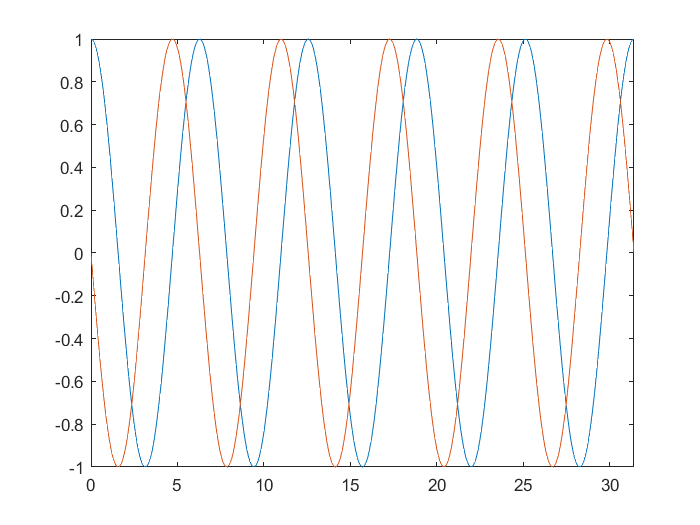

U=L\rhs;
plot(U)